
$$f\left(x\right)=\text{ }\frac{x^2 +6x+10}{x+3}$$


syms x;
f = (x^2 + 6*x + 10)/(x+3);

df = diff(f);

solutions = solve(df == 0, x);

Wykrez

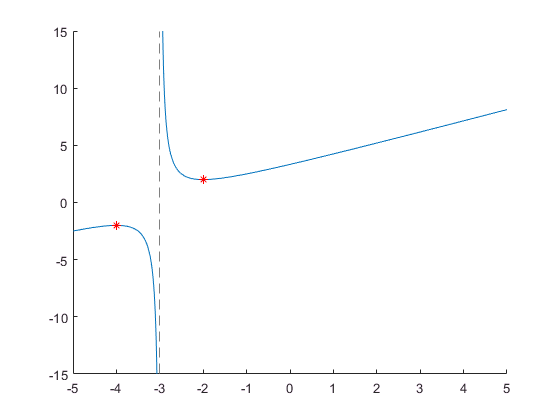

hold on;
fplot(f);
for i=1:length(solutions)
    x = solutions(i);
    val = subs(f);
    fplot(x, val, 'r*')
end

Monotoniczność

syms x;
f = (x^2 + 6*x + 10)/(x+3);

df = diff(f);

solutions = solve(df > 0, x, 'ReturnConditions', true)

solutions = struct with fields:
             x: [0×1 sym]
    parameters: [1×0 sym]
    conditions: [0×1 sym]
